## Lab 3

*Name: Joshua Yap*

*Lab Partner: Dane Thorn*

    This lab is focused on asking a statistical question and then performing the appropriate analyses. There are three problems that we will do this for. 

### Problem 1

We have temperature readings (metadata) associated with a particular experiment. For the experiment to work reliably, we need the temperature to be around 12K. The data is mostly within 12$\pm$0.4K. We want to identify and throw out data when the thermal control system and the thermometry were not working properly. We simulate 100k random 'good' data points below (thermometry fluctuations where we know the thermal control system was working properly), and add to that a few known 'bad' data points.

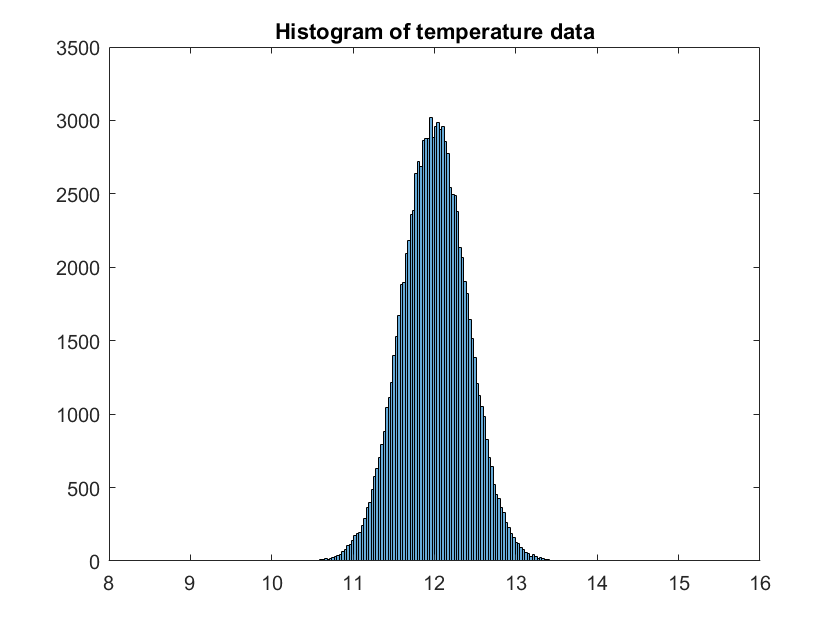

clear all; close all; clc
rng('default');
rng(1);
mu = 12;
sd = 0.4;
good = sd.*randn(1e5,1)+mu;
bad = [10.;10.3;2.1;0.;0.;15.6;22.3;12.7];
data1 = [good; bad];
histogram(data1)
xlim([8 16])
title('Histogram of temperature data')

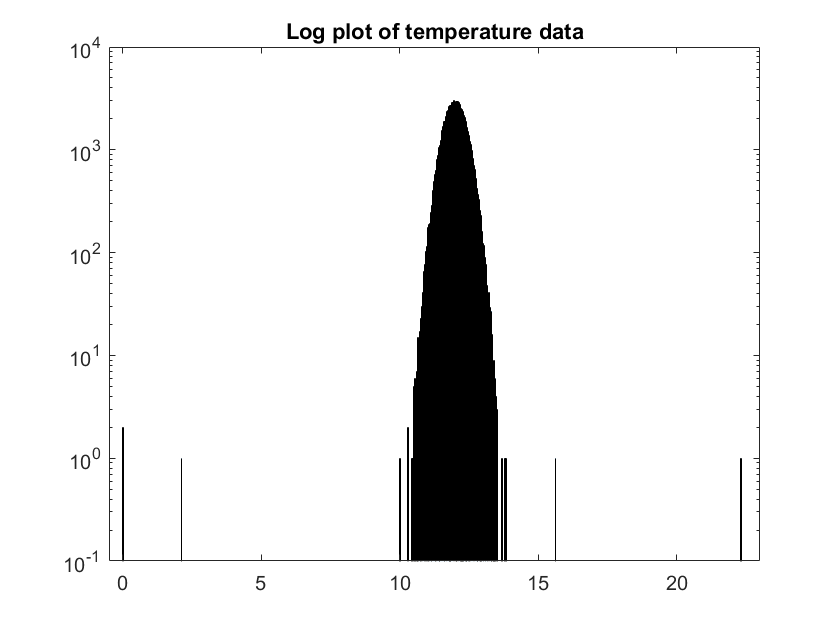

% hold on
% x = [8:0.1:16];
% y = 3000*normpdf(x,mu,sd);
% plot(x,y,'LineWidth',2)
% hold off
figure
histogram(data1)
set(gca,'YScale','log')
xlim([-0.5 23])
ylim([1e-1 1e4])
title('Log plot of temperature data')

The data appears to fit nicely into a Gaussian curve in the upper plot, but the outliers are obvious in the lower one. Given the goal of identifying bad data and throwing it out, we want to create a criteria for what we would consider bad data. Knowing that we have 8 bad data points out of 100,008 total data points, the probability that we choose a bad data point is

$P\left(\textrm{bad}\right)=\frac{8}{100,008}=7\ldotp 9994\times {10}^{-5}$.

It is therefore reasonable to say that we want to discard $7\ldotp 9994\times {10}^{-5}$ of the data. It is also reasonable to assume that the bad data points are at the tails of the distribution since we would expect a bad reading to be an outlier far away from the mean. In light of this, we want to discard $7\ldotp 9994\times {10}^{-5}$ from the tails of our distribution. Exploiting the symmetry of our distribution (ie. the outliers occur on both sides of the distribution), we can simply halve the probability and discard this from one of the tails. Our aim now is to convert this threshold probability $P_T$ to a threshold sigma value $\sigma_T$ and subsequently an x-offset $x_T$ on our distribution. We reflect $x_T$ about the mean to find the threshold on the other tail. We then want to know how well our statistical threshold did.

Statistical Question

Given a Gaussian distribution of good data points with mean 12 and standard deviation 0.4, what is the probability that we discard good points (omission) and keep bad points (commission) for a statistical threshold $\sigma_T$.

Math Question


$$P\left(\textrm{omission}\right)=\frac{n\left(\textrm{good}\;\textrm{points}\;\textrm{excluded}\right)}{n\left(\textrm{total}\;\textrm{points}\right)}$$



$$P\left(\textrm{commission}\right)=\frac{n\left(\textrm{bad}\;\textrm{points}\;\textrm{included}\right)}{n\left(\textrm{total}\;\textrm{points}\right)}$$


To find $\sigma_T$, we solve for it in the equation

$\int_{\sigma_T \;}^{\infty } \frac{1}{\sqrt{\;2\pi }}e^{-x^2 /2} =P_T ,\;P_T =3\ldotp 9997\times {10}^{-5}$.

To find $x_T$, we use the same probability $P_T$ and solve for $x_T$ in the equation

$\int_{12+x_T }^{\infty } \frac{1}{0\ldotp 4\sqrt{\;2\pi }}e^{-{\left(x-12\right)}^2 /\left(2\left(0\ldotp 4^2 \right)\right)} =P_T$.

Once we have $x_T$, we can evaluate our simulated data to see how many good points we throw out and how many bad points we keep.

% Solve for sigma
Pt = 3.9997e-5;
sigt = norminv(1-Pt);
% solve for xt
xt = norminv(1-Pt,mu,sd)-12;


$$\begin{array}{l}
\sigma_T =3\ldotp 9444\\
x_T =1\ldotp 5778
\end{array}$$


The bounds we want to impose on the good data are 12$\pm$1.5778. Everything outside these bounds will be discarded. Below we look through the list of good data points and pick out those that fall outside the bounds.

low = [];
high = [];
for j=1:length(good)
    temp = good(j);
    if temp<mu-xt
        % add to low
        low = [low temp];
    elseif temp>mu+xt
        % add to high
        high = [high temp];
    end
end

We also look at the list of bad data points and identify those that are within the bounds. The results are summarized in the truth table below.

With a threshold sigma $\sigma_T$ of 3.9444 and threshold x-offset of 1.5778 from the mean, we have

$P\left(\textrm{omission}\right)=\frac{4}{100,008}=3\ldotp 9997\times {10}^{-5}$,

$P\left(\textrm{commission}\right)=\frac{1}{100,008}=9\ldotp 9992\times {10}^{-6}$.

It was very effective in preventing false positives, but based on our knowledge of the what the good data is, could be improved to eliminate the true negatives.

We explore this further by first looking at how adjusting $\sigma_T$ changes the number of omissions. We test it over a range from $\sigma_T =3$ to $\sigma_T =5$ in steps of 0.1.

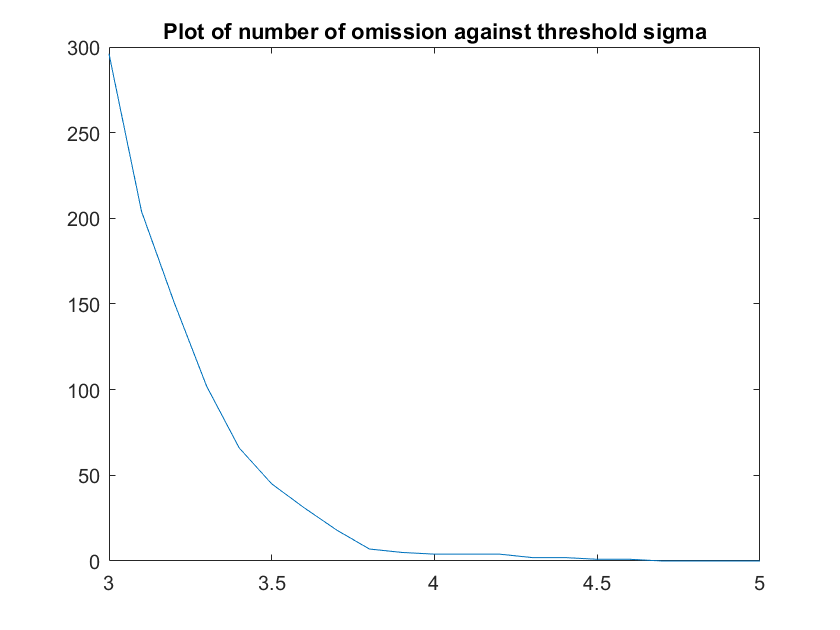

sig_test = 3:0.1:5;
count = zeros(1,length(sig_test));
for k=1:length(sig_test)
    omit = [];
    sig = sig_test(k);
    % compute x_test
    p_test = 1-normcdf(sig);
    x_test = norminv(1-p_test,mu,sd)-12;
    for j=1:length(good)
        temp = good(j);
        if temp<mu-x_test
            % add to omit
            omit = [omit temp];
        elseif temp>mu+x_test
            % add to omit
            omit = [omit temp];
        end
    end
    count(k) = length(omit);
end
plot(sig_test,count)
title('Plot of number of omission against threshold sigma')

The plot above shows that there is a relationship between the threshold sigma and the number of omissions. It follows the shape of the Gaussian tail, which makes sense because as we increase $\sigma_T$ linearly, we move further away from the mean at a constant rate so the decrease in the number of points outside the bounds looks like the Gaussian. We can be fairly confident of decreasing the number of omissions by increasing $\sigma_T$.

As for mistakes of commission, there is 1 bad data point that got into our data set when $\sigma_T =3\ldotp 9444$. This was unavoidable as it has a value of 12.7, only $\sigma =1\ldotp 75$ away from the mean. We cannot get rid of this data point without throwing out a significant amount of good data. As for the other bad data points, the values 10 and 10.3 may be falsely included if we increase $\sigma_T$ by a little bit. The others are outside the reasonable range of what we would increase it to. 15.6 is the next closest value, which is $\sigma =9$ away from the mean.

### Problem 2

We would like to look for an asteroid based on the difference in its position between subsequent images, and want a 5 sigma detection of movement. We are given a 2D Gaussian of positional uncertainty. The brightness of each pixel on the given histogram corresponds to a likelihood of finding stars that have moved by the coordinates ($\Delta x$ and $\Delta y$) of the pixel. We can use Pythagoras' theorem to convert this 2D distribution into a 1D parameterization

$\Delta r=\sqrt{\left(\Delta x{\left.\right)}^2 +{\left(\Delta y\right)}^2 \right.}$.

This allows us to express the distance travelled with a Rayleigh distribution. We can do this because the distance formula above follows the form of a chi distribution with 2 degrees of freedom ($\Delta x$ and $\Delta y$), which is the special case represented by the Rayleigh distribution. We are told that the RMS is 1 arcsecond for the 2D Gaussian.


$$\begin{array}{l}
{\mathrm{RMS}}_x =\sqrt{\frac{1}{N}\left\lbrack \left(\Delta x_1 {\left.\right)}^2 +\left(\Delta x_2 {\left.\right)}^2 +\left(\Delta x_3 {\left.\right)}^2 +\ldotp \ldotp \ldotp +\left(\Delta x_N {\left.\right)}^2 \right.\right.\right.\right.\right\rbrack }=1\\
{\mathrm{RMS}}_y =\sqrt{\frac{1}{N}\left\lbrack \left(\Delta y_1 {\left.\right)}^2 +\left(\Delta y_2 {\left.\right)}^2 +\left(\Delta y_3 {\left.\right)}^2 +\ldotp \ldotp \ldotp +\left(\Delta y_N {\left.\right)}^2 \right.\right.\right.\right.\right\rbrack }=1
\end{array}$$


We note a similarity between the form of the RMS and standard deviation:


$$\sigma =\sqrt{\frac{1}{N-1}\sum_{i=1}^N {\left(x_i -\bar{x} \right)}^2 }\ldotp$$


$\bar{x}$, the average values of $\Delta x$ and $\Delta y$, in our data are zero, and $N$ is large enough such that

$\sqrt{\frac{1}{N}}\approx \sqrt{\frac{1}{N-1}}$.

$\sigma$ reduces to

$\sigma_x ={\mathrm{RMS}}_x =1$,

$\sigma_y ={\mathrm{RMS}}_y =1$.

As such, the pdf of the resulting Rayleigh distribution is

$f\left(x\right)=\frac{x}{\sigma^2 }e^{-\frac{x^2 }{2\sigma^2 }} =x\cdot e^{-\frac{x^2 }{2}}$.

Statistical Question

The presence of an asteroid is represented by a larger distance moved from one image to the next. Given a background Rayleigh distribution of distance stars moved from one image to the next, what is the distance an asteroid must move to have a 5 sigma detection?

Math

First find $P\left(5\sigma \right)$ using


$$P\left(5\sigma \right)=\int_5^{\infty } \frac{1}{\sqrt{2\pi }}e^{-\frac{x^2 }{2}} \;\textrm{dx},$$


the standard normal distribution. Then solve for $x_a$ in


$$\int_{x_a }^{\infty } x\cdot e^{-\frac{x^2 }{2}} \;\textrm{dx}=P\left(5\sigma \right)\ldotp$$


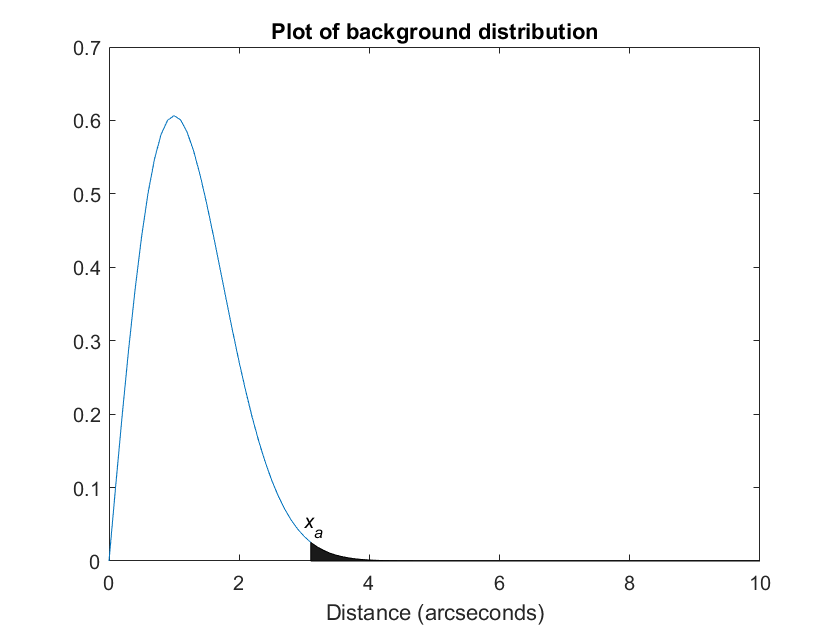

pd_asteroid = makedist('Rayleigh',1);
x = 0:0.1:10;
figure
plot(x,pdf(pd_asteroid,x))
hold on
area(x(32:end),pdf(pd_asteroid,x(32:end)),'FaceColor',[0.1 0.1 0.1])
title('Plot of background distribution')
xlabel('Distance (arcseconds)')
text(3,0.05,'\itx_{a}')
hold off

The figure above visualizes what we are trying to do. We want to integrate the area under the upper tail from $\infty$ down until we get an area equal to $P\left(5\sigma \right)$. The x-value $x_a$ that we stop at is then the distance an asteroid must move for a 5-sigma detection.

### Problem 3

This problem deals with moon shadow detection using cosmic ray counts. We observe the sky for 15 8-hour nights, which equates to 7200 minutes. Our data exhibits features of a Poisson distribution, namely that the experiment consists of counting gamma rays in a time interval, and the count of gamma rays is discrete.

Statistical Question

We expect that a moon-sized observation of the sky without the moon gives us 1 cosmic ray per minute. A moon shadow causes fewer cosmic rays to be detected. In 7200 1-minute intervals, what is the significance of a moon shadow detection if 6800 cosmic rays are detected?

Math

The distribution of a 1-minute interval is Poisson with a mean of 1. Find the probability distribution of the background (${\textrm{pdf}}_b$) by convolving this distribution with itself 7200 times. Then take the integral

$P\left(\textrm{moon}\right)=\int_0^{6800} {\textrm{pdf}}_b \;\textrm{dx}$.

Convert $P\left(\textrm{moon}\right)$ to a sigma value using the norminv function in Matlab.

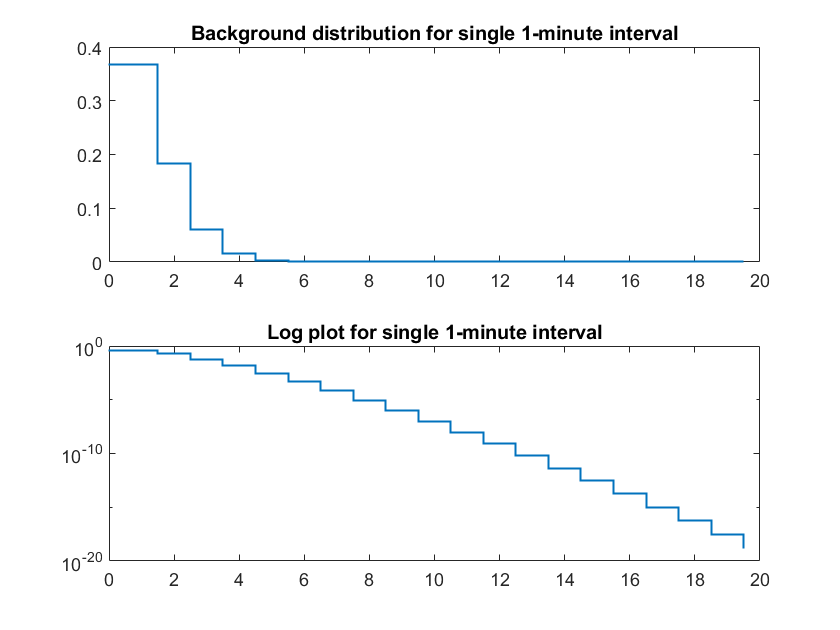

% 1 minute distribution
x = [0:20];
avg = 1;
poiss1 = makedist("Poisson",'lambda',avg);
figure
subplot(2,1,1)
stairs(x-0.5,pdf(poiss1,x),'LineWidth',1)
title('Background distribution for single 1-minute interval')
xlim([0 20])

subplot(2,1,2)
stairs(x-0.5,pdf(poiss1,x),'LineWidth',1)
title('Log plot for single 1-minute interval')
xlim([0 20])
set(gca,'YScale','log')

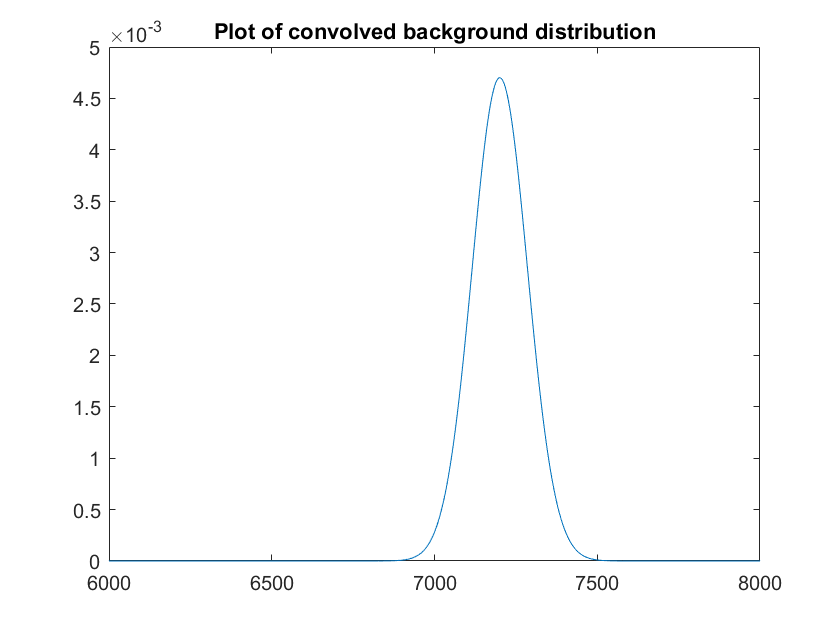

% Convolve 7200 times
poiss_iso = pdf(poiss1,x);
poiss7200 = poiss_iso;
for j=1:7200
    poiss7200 = conv(poiss_iso,poiss7200);
end
xconv = 0:length(poiss7200)-1;
figure
plot(xconv,poiss7200)
title('Plot of convolved background distribution')
xlim([6000 8000])

The background distribution for 7200 intervals now looks like the plot above. It leaves us to integrate the lower tail from zero to 6800 in order to find a probability for the moon shadow. We subsequently convert this to a sigma value.

pmoon = sum(poiss7200(1:6801));
sigmoon = norminv(1-pmoon);
disp(table(pmoon,sigmoon,'VariableNames',{'P(moon)','sigma'}))

     P(moon)      sigma 
    __________    ______

    9.5642e-07    4.7624



The significance of the moon shadow detection is 4.7624$\sigma$, not high enough to claim a discovery.

Note that the convolved distribution looks like a Gaussian. According to the central limit theorem, the normalized sum of independent random variables tends towards a Gaussian distribution. We explore this by approximating the distribution above with a Gaussian and computing the sigma value for this approximation.

The parameters to be used for the approximation are

$\mu =7200$,

$\sigma =\sqrt{7200}$.

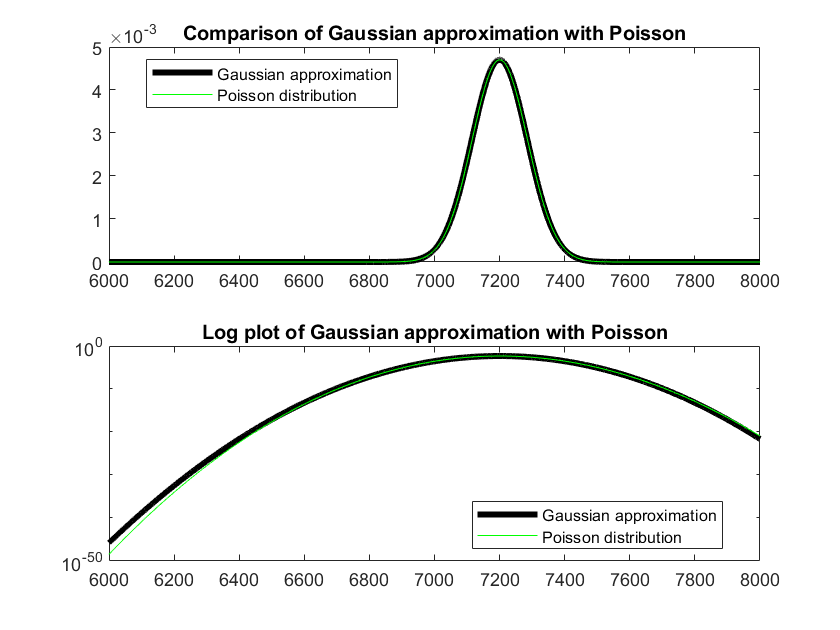

pd_approx = makedist('Normal',7200,sqrt(7200));
x = 6000:8000;
approx = pdf(pd_approx,x);
figure
subplot(2,1,1)
plot(x,approx,'LineWidth',3,'Color','k')
hold on
plot(xconv,poiss7200,'LineWidth',0.5,'Color','g')
title('Comparison of Gaussian approximation with Poisson','FontSize',11)
legend('Gaussian approximation','Poisson distribution','Location','best')
xlim([6000 8000])
hold off
subplot(2,1,2)
plot(x,approx,'LineWidth',3,'Color','k')
hold on
plot(xconv,poiss7200,'LineWidth',0.5,'Color','g')
title('Log plot of Gaussian approximation with Poisson','FontSize',11)
legend('Gaussian approximation','Poisson distribution','Location','best')
xlim([6000 8000])
set(gca,'YScale','log')
hold off

The log plot shows some deviation at the left edge of the plot range, but the magnitude of the deviation appears negligible compared to the scale of the probabilities we are interested in. We move on to compute the sigma value obtained from the Gaussian approximation.

papprox = normcdf(6800,7200,sqrt(7200));
sigapprox = norminv(1-papprox);
disp(table(papprox,sigapprox,'VariableNames',{'P_approx','sigma'}))

     P_approx     sigma
    __________    _____

    1.2142e-06    4.714



A comparison of the two distributions are in the table below.

The error between the approximation and the actual distribution is not as negligible as I intially thought, with a difference of 0.0484$\sigma$ or 1%. A reason for this could be that the distributions continue to diverge as we decrease along the x-axis and the sum of these divergences cause more of a difference in the cumulative distribution than originally thought.